## Generate a Fourier series from 2 to 4 function pieces

#### Number of pieces

pieces_n = 4;

The values on unused pieces will be ignored

#### Piece 1

f1 = @(t) 1;
f1_start_point = 0;
f1_end_point = 1;

#### Piece 2

f2 = @(t) 2;
f2_start_point = 1;
f2_end_point = 2;

#### Piece 3

f3 = @(t) 3;
f3_start_point = 2;
f3_end_point = 3;

#### Piece 4

f4 = @(t) 4;    
f4_start_point = 3;
f4_end_point = 4;

#### Calculation requeriments

harmonic_n = 10;        % Matlab is a horrible language and piece of software that performs poorly with lots of recursion. I recommend staying below 255.
harmonic_power_n = 5;   % Number of harmonics to use to calculate the average power.

#### Display parameters

graph_left = 3;
graph_right = 3;

Function definition

% oldparam = sympref ('HeavisideAtOrigin', 1);
u = @(t) heaviside(t);

if pieces_n == 2
    T = f2_end_point - f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));
elseif pieces_n == 3
    T = f3_end_point-f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point)) + f3(t).*(u(t - f3_start_point) - u(t - f3_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));
else
    T = f4_end_point - f1_start_point;

    fT = @(t) f1(t).*(u(t - f1_start_point) - u(t - f1_end_point)) + f2(t).*(u(t - f2_start_point) - u(t - f2_end_point)) + f3(t).*(u(t - f3_start_point) - u(t - f3_end_point)) + f4(t).*(u(t - f4_start_point) - u(t - f4_end_point));
    f = @(t) fT(t - T*floor((t - f1_start_point) / T));
end

Parameter initialization

w = 2*pi/T;
a_n = zeros(1, harmonic_n + 1);
b_n = zeros(1, harmonic_n + 1);
a_m = zeros(1, harmonic_n + 1);
phi = zeros(1, harmonic_n + 1);
c = zeros(1, harmonic_n + 1);

Calculation of coeficients $a_n, \ a_m, \ b_n, \ c, \  \varphi$

for n = 0 : harmonic_n
    if pieces_n == 2
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point);    
    elseif pieces_n == 3
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*cos(n * w * t), f3_start_point, f3_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*sin(n * w * t), f3_start_point, f3_end_point);
    else
        a_n(n+1) = (2/T) * integral( @(t)f1(t).*cos(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*cos(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*cos(n * w * t), f3_start_point, f3_end_point) + (2/T) * integral(@(t)f4(t).*cos(n * w * t), f4_start_point, f4_end_point);
        b_n(n+1) = (2/T) * integral( @(t)f1(t).*sin(n * w * t), f1_start_point, f1_end_point) + (2/T) * integral(@(t)f2(t).*sin(n * w * t), f2_start_point, f2_end_point) + (2/T) * integral(@(t)f3(t).*sin(n * w * t), f3_start_point, f3_end_point) + (2/T) * integral(@(t)f4(t).*sin(n * w * t), f4_start_point, f4_end_point);
    end

    if abs(a_n(n+1)) < 5*10^(-15)
        a_n(n+1) = 0;
    end
             
    if abs(b_n(n+1)) < 5*10^(-15)
        b_n(n+1) = 0;
    end

    c(n+1) = ( a_n(n+1) - 1j*b_n(n+1) ) / 2;    
    a_m(n+1) = sqrt( (a_n(n+1))^2 + (b_n(n+1))^2 );
    phi(n+1) = angle( a_n(n+1) - b_n(n+1)*1j );
end

Partial sum until the nth harmonic of the fourier series

S = @(t) a_n(1)/2;     
for n = 1 : harmonic_n      
    S = @(t) S(t) + a_n(n+1)*cos(n*w*t) + b_n(n+1)*sin(n*w*t);
end

Calculation of average power and amplitude

stem(0:1:harmonic_n, 2*abs(c))

f2 = @(t) f(t).^2;
if pieces_n == 2
    P = 1 / T * integral(f2, f1_start_point, f2_end_point);
elseif pieces_n == 3
    P = 1 / T * integral(f2, f1_start_point, f3_end_point);
else 
    P = 1 / T * integral(f2, f1_start_point, f4_end_point);
end

P_k = (a_n(1) / 2)^2;

for n = 2 : harmonic_power_n + 1
    P_k = P_k + (1/2) * (a_m(n))^2;
end

stdout_1 = "Average power = " + P;
stdout_2 = "Percentage of the total average power = " +  (P_k/P)*100 + "%";

Plotting the functions

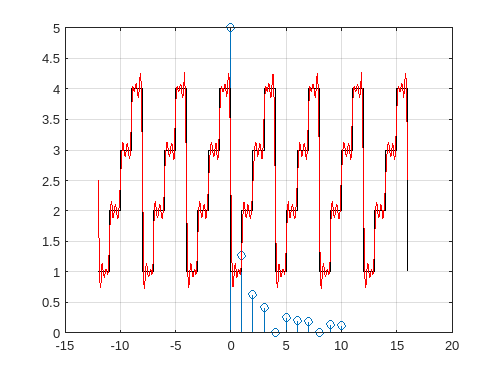

hold on

if pieces_n == 2
    fplot(f, [f1_start_point - graph_left * T, f2_end_point + graph_right * T], 'k')
    I = linspace(f1_start_point - graph_left * T, f2_end_point + graph_right * T, 650);
elseif pieces_n == 3
    fplot(f, [f1_start_point - graph_left * T, f3_end_point + graph_right * T], 'k')
    I = linspace(f1_start_point - graph_left * T, f3_end_point  +graph_right * T, 650);
else
    fplot(f, [f1_start_point - graph_left * T, f4_end_point + graph_right * T], 'k')
    I = linspace(f1_start_point - graph_left * T, f4_end_point + graph_right * T, 650);
end

plot(I, S(I), 'r')
grid on

figure

disp(stdout_1);

Average power = 7.5


disp(stdout_2);

Percentage of the total average power = 98.476%



ns = (0:harmonic_n)';
var_table = table(ns, a_n', b_n', c', a_m',phi', 'VariableNames', {'n', 'a_n', 'b_n', 'c_n', 'amplitude', 'phase'});
disp(var_table);

    n     a_n      b_n            c_n         amplitude    phase 
    __    ___    ________    _____________    _________    ______

     0     5            0    2.5+0i                  5          0
     1     0      -1.2732      0-0.63662i       1.2732     1.5708
     2     0     -0.63662      0-0.31831i      0.63662     1.5708
     3     0     -0.42441      0-0.21221i      0.42441     1.5708
     4     0            0      0+0i                  0          0
     5     0     -0.25465      0-0.12732i      0.25465     1.5708
     6     0     -0.21221      0-0.1061i       0.21221     1.5708
     7     0     -0.18189      0-0.090946i     0.18189     1.5708
     8     0            0      0+0i                  0          0
     9     0     -0.14147      0-0.070736i     0.14147     1.5708
   